# Changes status randomly at pipes during simulation.

This example contains: Load a network. Get pipe count. Get pipe indices. Run step by step hydraulic analysis. Set status random 0/1 for pipes. Plot flows. Unload library.

Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


Load a network.

d = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.003}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded sucessfuly.


Get pipe count.

pipe_count = d.getLinkPipeCount;

Get pipe indices.

pipe_indices = d.getLinkPipeIndex;

Run step by step hydraulic analysis.

d.openHydraulicAnalysis;
d.initializeHydraulicAnalysis;
i=1;tstep=1; F=[];
while (tstep>0)
    % Set status random 0/1 for pipes.
    Status = round(rand(1,pipe_count))';

    t=d.runHydraulicAnalysis;
    d.setLinkStatus(pipe_indices, Status); i=i+1;
    F = [F; d.getLinkFlows];
    tstep=d.nextHydraulicAnalysisStep;
end
d.closeHydraulicAnalysis;

Plot flows.

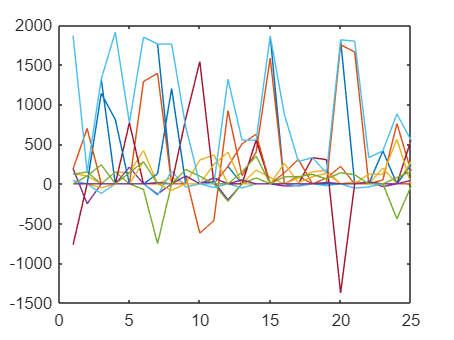

plot(F)

Unload library.

d.unload

EPANET Class is unloaded
